# **GWSAT ATTITUDE DETERMINATION**

**1.THREE-AXIS MAGNETOMETER (TAM) MODEL **

The magnetometer model was performed asociated with a gausian noise 

$mag_{meas} = mag_{real}+\epsilon$   (1)

Where $mag_{meas}$ is the magnitude measured by the magnetometer, $mag_{real}$ is the real magnetic field and $\epsilon$ is the gaussian noise.

**2.SUN POSITION**

 To obtain the position of the sun in the IGRF in this investigation was used the equation described by [2]. In [2] it is mentioned that the position of the sun respect ot the Earth can be determined as follows:

The mean longitude $\phi_{\odot}$:

$\phi_{\odot} = 280.460° + 36,000.771T_{UT1}$ (2)

The mean anomaly of the sun $M_{\odot}$

$M_{\odot} = 357.5277233° + 35999.05034 T_{UT1}$  (3)

Where:

$T_{UT1}=\frac{JD(Y,M,D,h,m,s)-2,451,545}{36.525}$  (4)

And the Julian Day is calculated by the following formula.


$$JD(Y,M,D,h,m,s)=1,721,013.5 + 367 Y -INT \left \{ \frac{7}{4} \left[ Y + INT \left ( \frac{M+9}{12} \right ) \right] \right \} + INT \left ( \frac{275M}{9} \right ) + D + \frac{60h+m+s/60}{1440}$$
   

(5)

Finally, the longitude of the ecliptic is deterimined in degrees as:

$\phi_{ecliptic} =  \phi_{\odot}+1.914666471°sin(M_{\odot})+0.019994643sin(2M_{\odot})$   (7)

The obliquity of the ecliptic is given by

$\varepsilon = 23.439291° - 0.0130042T_{UT1}$   (8)

The unit vector in the direction from the Earth to the Sun is then:

$e_{{\;}_{\otimes \odot \;} } =\left\lbrack \begin{array}{c}
\cos \left(\phi_{\textrm{ecliptic}} \right)\\
\cos \left(\varepsilon \right)\sin \left(\phi_{\textrm{ecliptic}} \right)\\
\sin \left(\varepsilon \right)\sin \left(\phi_{\textrm{ecliptic}} \right)
\end{array}\right\rbrack$    (9)

**3. Eclipse Condition**

The eclipse condition was calculated with the algorithm 35 described in [3]. This is based in the SIGHT and Light problem which attemps to determina if between two position vectors exists *line of sight. *

The algorithm is based on the alfano approach (1991) and it attempts to avoid trigonometric operations. It is based in the following figure:

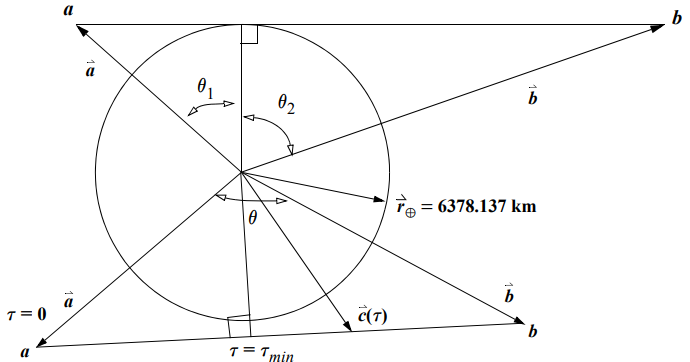

Alfano proposes a parametric representation of a line between the position vector vectors $\overrightarrow{a}$ and $\overrightarrow{b}$ :

$\overrightarrow{c(\tau)}=\overrightarrow{a}+(\overrightarrow{b}-\overrightarrow{a})\tau$  (10)

Where:

 
$$\overrightarrow{c(\tau)} = \overrightarrow{a}  \rightarrow \tau = 0$$



$$\overrightarrow{c(\tau)} = \overrightarrow{b} \rightarrow \tau = 1$$


In this case alfano explains that it is necessary to find the value of $\tau$ that minimizes the distance to the central body $\overrightarrow{c(\tau)}$ and then compare this with the magnitude of the earth radius. But in this case, to avoid to solve square roots, the norm square of each value is considered so considering $\overrightarrow{a}=a_1\hat{i}+a_2\hat{j}+a_3\hat{k}$ and $\overrightarrow{b}=b_1\hat{i}+b_2\hat{j}+b_3\hat{k}$:

$|\overrightarrow{c(\tau)}|^2 = (a_1+(b_1-a_1)\tau)^2+(a_2+(b_2-a_2)\tau)^2+(a_3+(b_3-a_3)\tau)^2$  (11)

Then, to obtain the value that minimizes the $\overrightarrow{c}$, the derative is calculated and compared with zero.

$\frac{d|\overrightarrow{c(\tau)}|^2}{d\tau} = 0$   (12)

Solving the above equation, we obtain that $\tau_{min}$ is. 

$\tau_{min} = \frac{|\overrightarrow{a}|^2-\overrightarrow{a} \cdot \overrightarrow{b}}{|\overrightarrow{a}|^2+|\overrightarrow{b}|^2-2\overrightarrow{a}\cdot \overrightarrow{b}} = \frac{\overrightarrow{a}\cdot(\overrightarrow{a}-\overrightarrow{b})}{|\overrightarrow{a}-\overrightarrow{b}|^2}$  (13)

Remplazing (13) in (11) we obtain

$\overrightarrow{c}(\tau)_{min} = (1-\tau_{min})|\overrightarrow{a}|^2+(\overrightarrow{a}\cdot \overrightarrow{b})\tau_{min}$  (14)

The algorithm is explained as appears below:

if $\tau_{min}$ < 0 or $\tau_{min}$ >1 there is lins of sight or there is no eclipse due to both vectors are in the same quadrant with respect to the atracting body (earth).

If $\tau_{min}$ is between $[0,1]$ then the magnitude $|\overrightarrow{c}({\tau_{min}})|^2$ is compared with $R_{\oplus}^2$. if $|\overrightarrow{c}({\tau_{min}})|^2 < R_{\oplus}^2$ there is no LOS between the vectors.

**3. DIGITAL SUN SENSOR (DSS) MODEL**

The digital sun sensor model is based in the SAMPEX sun sensor model described in [1]. The body Sun vector is computing using:

$b_{\textrm{sun}} =\frac{1}{\sqrt{x^2 +z^2 +h^2 }}\left\lbrack \begin{array}{c}
-\textrm{nx}\\
\sqrt{h^2 -\left(n^2 -1\right)\left(x^2 +z^2 \right)}\\
-\textrm{nz}
\end{array}\right\rbrack$  (2)

Where n is the refraction index of the glass and h is the glass thickness in cm. To simulate the sun sensor from the inertial sun vector $r_{sun}$, this vector is first converted to body frame using attitude matrix: $b_{sun} \equiv [b_{sun1} b_{sun2} b_{sun3}]^T = Ar_{sun}$. Then the components x and z are taken from computed using (1):

$z=\pm\frac{hb_{sun3}}{\sqrt{n^2-b^2_{sun1}-b^2_{sun3}}}$    (3)

$x=\frac{zb_{sun1}}{b_{sun3}}$    (4)

where the sign of z is easily determined by the known body motion. 


$$s3 = -\frac{n \cdot z}{\sqrt{x^2 + z^2 + h^2}}=-\frac{n \cdot z}{\sqrt{\left(\frac{z \cdot \text{sun\_b}(1)}{\text{sun\_b}(3)}\right)^2 + z^2 + h^2}}
$$



$$z = -z \cdot \text{sign}(s3 \cdot \text{sun\_b}(3))
$$


A sun sensor measures  azimuth $\phi$, and a coelevation $\theta$, which are computed by:


$$\phi = atan2(x,z)$$



$$\theta = tan^{-1}\left [ \frac{n\sqrt{x^2+z^2}}{\sqrt{h^2-(n^2-1)(x^2+z^2)}} \right ]$$


Measurements are obtained by adding zero-mean Gaussian white-noise to $\phi$ and $\theta$ with standard deviations $\sigma_{\phi}$ and $\sigma_{\theta}$. To produce the simulated body vector measurements, first the tangent of the angles for the rotation arround -x and z axes, denoted by $\alpha$ and $\beta$, are computing using:


$$tan \alpha = tan \theta sin \phi$$



$$tan \beta = tan \theta cos\phi$$


Where $\phi$ and $\theta$ are the measured values, including noise. The measured unit vecto is given by:


$$b_{\textrm{sun}} =\pm \frac{1}{\sqrt{1+\tan^2 \alpha +\tan^2 \beta }}\left\lbrack \begin{array}{c}
\tan \alpha \\
1\\
\tan \beta 
\end{array}\right\rbrack$$


*The resolution of the sun sensor is simulated with th "round command".

where "meas" is the measurement including noise and "res" is the sensor resolution.

**3. START SENSOR MODEL**

**5. FIELD OF VIEW (FOV)**

In [4], the Fov is defined as the region at which the star sensor is capable to see and detect stars in the sky. In this simulation is used an algorithm taking into consideration that stars are in the infinity according to hippoargos catalog, the pointing vector is denoted as $u$, $d$ is the angle between the star location and $u$, and the $Fov$ angle describes a conical region according to the following image.

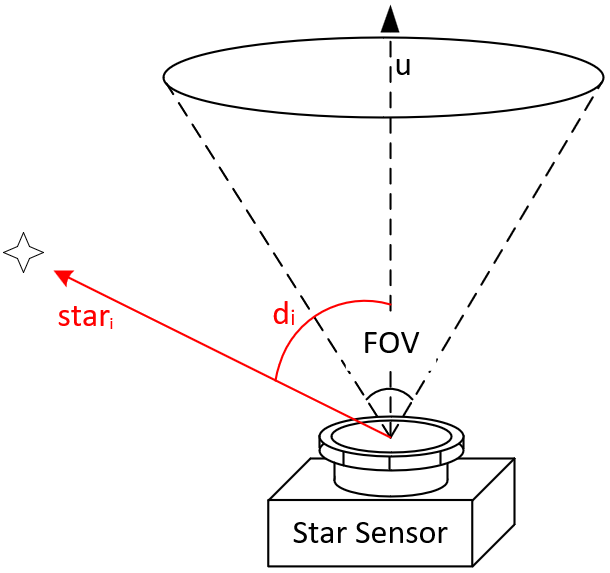

The algorithm operation can be summarized as follows:

- **Normalization of the **$u$** vector: **The unit vector $u$ is normalized to ensure it represents a unit direction of the field of view in the celestial sphere. 

- **Iteration: **The function iterates through the star catalog, examining each star one by one. Each star is represented as a row in the catalog, and its coordinates are considered.

- **Angular Calculation: **For each star position denoted as $\text{star}_i$ , the angular separation, denoted as $d_i$, between the direction of the field of view ($u$) and the star's direction is computed. This angular separation, $d_i$, is calculated using the dot product of the direction cosines of the two directions.


$$d_i = \arccos\left(\frac{u \cdot star_i}{\|u\| \|star_i||}\right)$$


- **Field of View Check:** If the angular separation $d_i$ is found to be less than half of the specified field of view $\frac{fov}{2}$, the star is deemed to be within the field of view.

**4. Hippargos catalog**

The "Hipparcos Catalog" (also known as the "Hipparcos Star Catalog") was a space project of the European Space Agency (ESA) that operated in the 1990s. Its primary objective was to measure with high precision the positions, movements, and parallaxes of a large number of stars in the Milky Way. The resulting catalog, called the "Hipparcos Catalog," was an invaluable resource for astronomers and contributed significantly to our understanding of interstellar space and the distribution of stars in the galaxy.

**2. The TRIAD Algorithm**

Als known as the triaxial attitude determination. This method use exactly two vector measurements. (Usually sun vector and the Earth's magnetic field vector).

Suppose we have a pair of vectors in the boy frame and in the reference frame denoted as.

Body frame vectors:$b_1$ and $b_2$.

Reference frame vectors: $r_1$and $r_2 \ldotp$

The attitude matrix doesn't will be obtained if the vectors are parallel or antiparallel. 

The attitude matrix that rotates vector from the reference frame to the spacecraft body frame, is denoted as

${\textrm{Ar}}_i =b_i$ , for $i = 1, 2$   (1)

From eq (1) we can get.

$b_1\cdot b_2 = (Ar_1)\cdot(Ar_2)=r^T_1A^TAr_2=r_1\cdot r_2$    (2)

Equation (2) is true for free error measurements, but not generally true in precense of errors. The classic TRIAD is based on the assumption that one of the unit vectors ($b_1
$) is much more accurately determined than the other, so the estimates satisfies $Ar_1=b_1$ exactly, but $Ar_2=b_2$ only approximately.

TRIAD is based on the idea that there are an orthonormal right-handed triad of vectors $(v_1,v_2,v_3)$ in the reference frame and the triad $(w_1,w_2,w_3)$ in the spacecraft body frame. So the attitude matrix is.

$A = [w_1,w_2,w_3][v_1,v_2,v_3]^T=\sum_{i=1}^3w_iv_i^T$    (3)

TRIAD forms the triad $\{v_1,v_2,v_3\}$ from $r_1$ and $r_2$, and the triad $\{w_1,w_2,w_3\}$ from $b_1$ and $b_2$ by means of

$v_1=r_1, v_2 = r_{\times} = \frac{r_1\times r_2}{||r_1 \times r_2||}, v_3 = r_1 \times r_{\times}$        (4)

$w_1=b_1, w_2 = b_{\times} = \frac{b_1\times b_2}{||b_1 \times b_2||}, w_3 = b_1 \times b_{\times}$   (5)

Then the estimate of the attitude matrix, indicated by a caret, is given by Eq (3)

$\hat{A}_{TRIAD} = b_1r_1^T + (b_1\times b_{\times})(r_1\times r_{\times})^T+b_{\times}r_{\times}^T$   (6)

The following code shows the implementation of the proposed algorithm:

The TRIAD is independed of the component of $b_2$ along $b_1$ and the component of  $r_2$ along $r_1$. 

**2.Optimized TRIAD**

The optimized TRIAD is a linear combination between two TRIAD algorithms, called TRIAD-I and TRIAD-II. The first algorithm generates the matrix $A_1$, and the second generates the matrix $A_2$. It consists of the construction of two vectors triads using two pairs of vector measurements: two in the orbital reference frame, noted $v_1$  and $v_2$, and two in the body reference frame, noted $w_1$ and $w_2$. Let $\sigma_1$ and $\sigma_2$ be the measured noises of $w_1$ and $w_2$, respectively.

For the TRIAD -I algorithm, we define:


$$r_1 =\frac{w_1 }{{\left|w_1 \right|}};\ \ \ \ r_2 =\frac{r_1 \times w_2 }{|r_1 \times w_2 |};\ \ \ r_3 =r_1 \ \times r_2$$



$$s_1 =\frac{v_1 }{{\left|v_1 \right|}};\ \ \ \ s_2 =\frac{s_1 \times v_2 }{|s_1 \times v_2 |};\ \ \ s_3 =s_1 \ \times s_2$$


The matrix $A_1$ is expressed as:


$$A_1 =r_1 \ldotp s_1^T +r_2 \ldotp s_2^T +r_3 \ldotp s_3^T$$


For the TRIAD-II algorithm, we define


$$r_5 =\frac{w_2 }{{\left|w_2 \right|}};\ \ \ \ r_2 ={\frac{r_1 \times w_1 }{|r_1 \times w_1 |}}_{\;} \ ;\ \ \ r_4 =r_5 \ \times r_2$$



$$s_5 =\frac{v_2 }{{\left|v_2 \right|}};\ \ \ \ s_2 =\frac{s_1 \times v_1 }{|s_1 \times v_1 |};\ \ \ s_4 =s_5 \ \times s_2$$


And the $A_2$ is expressed as:


$$A_2 =r_5 \ldotp s_5^T +r_2 \ldotp s_2^T +r_4 {\ldotp s}_4^T$$


Then the optimization attitude matrix $\hat{A'}$  is calculated as:


$$\hat{A^{\prime } } =\frac{\sigma_2^2 }{\sigma_1^2 +\sigma_2^2 }A_1 +\frac{\sigma_1^2 }{\sigma_1^2 +\sigma_2^2 }A_2$$


Since $\hat{A'}$ is a sum of two orthogonal matrices, $\hat{A'}$ is nos orthogonal so an orthogonalization is required. Finally, the attitude matrix of optimized TRIAD is expressed as:


$$\hat{A} =0.5\left\lbrack {\hat{A} }^{\prime } +{{\left({\hat{A^{\prime } } }^{-1} \right)}}^T \right\rbrack$$


**3. Wahba's Problem**

The TRIAD method can be improved in two ways by allowing arbirary weighting of the measurements and by allowing the use of more than two measurements for example star trackers, magnetometers, etc. Wahba's problem is to find the orthogonal matrix A with determinant +1 that minimizes the loss function:


$$L(A) \equiv \frac{1}{2}\sum^N_{i=1} a_i||b_i-Ar_i||^2$$


Where $b_i$ is a set of N unit vectors measured in a spacecraft's body frame, $r_i$ are its corresponding unit vectors in a reference frame, $a_i$ are non-negative weights. The waha's problem can be solved in the following form:


$$L(A)=\lambda_0 -tr(AB^T)$$


Where:


$$\lambda_0 \equiv \sum_{i=1}^N a_i$$


and B is defined by:


$$B \equiv \sum_{i=1}^N a_ib_ir_i^T$$


Here, we can notice that the loss fuction is minimized when $tr(AB^T)$ is maximized. Several ways to solve the Wahbas problem are presented in the following form:

**4. Quaternion Estimator (QUEST)**

The Quest method stimator is based on the Paul Davenport method. According to [2], the Wahba's loss function then it is described as:

 
$$L\left(A\left(q\right)\right)\equiv \lambda {\;}_0 -\sum_{i=1}^N a_i b_i^T \;\Xi^T \left(q\right)\psi \left(q\right)r_i =L\left(A\left(q\right)\right)=\lambda_0 -q^T K\left(B\right)q$$


Where K(B) is the symmetric traceless matrix:


$$K\left(B\right)=\left\lbrack \begin{array}{cc}
B+B^T -\left(\textrm{trB}\right)I_3  & z\\
z^T  & \textrm{trB}
\end{array}\right\rbrack$$


and


$$z=\sum_{i=1}^N a_1(b_i\times r_i)$$


The eigenvalue/eigenvector decomposition of K can be writen as:


$$K(B) = \sum_{i=1}^4 \lambda_iq_iq_i^T$$


Where $q_i$ is the eigenvector with eigen calue $\lambda_i$, and the eigenvalues are labeled so that $\lambda_{max} \equiv \lambda_1\geq\lambda_2\geq\lambda_3\geq\lambda_4$.

In [2] it is mentioned that the optimal quaternion is the normalized eigenvector of K corresponding to the largest eigenvalue.


$$\hat{q} = q_1$$


However, this algorithm usually doesn't have only one solution due to sometimes two largest eigen values of K(B) can exists.

**Evaluate reference Frames**

Start orbit propagator

startTime = datetime(2023,08,30,12,35,38);
stopTime = startTime + hours(8.5);
sampleTime = 60;
sc = satelliteScenario(startTime,stopTime,sampleTime);

Set satellite orbital parameters

orbit.semiMajorAxis = 500E3+6378E3;
orbit.eccentricity = 0;
orbit.inclination = 97.34; 
orbit.rightAscensionOfAscendingNode = 313.131; 
orbit.argumentOfPeriapsis = 0; 
orbit.trueAnomaly = 0; 

Create satellite 

satSGP4 = satellite(sc, orbit.semiMajorAxis, orbit.eccentricity, orbit.inclination, ...
        orbit.rightAscensionOfAscendingNode, orbit.argumentOfPeriapsis, orbit.trueAnomaly);

Get the model reference model based on WMM model with these wrldmagm inputs:

- model_epoch - Epoch of WMM model.

- decimal_year - Scalar value representing the decimal year within the epoch for which the data was generated.

model_epoch = '2020';       %WMM2020     (2020-2025) (default)
decimal_year = 2023;
wgs84 = wgs84Ellipsoid;

### **1.1. Evaluate Magnetic Field Reference Frames**

#### **1.1.1. NED Frame**

Evaluate the magnetic Field in the stop Time so first we need to evaluate satellite position.

[positionGCRF, ~] = states(satSGP4,stopTime,"CoordinateFrame", "inertial");

Turn ECI position vector to geodetic position in LLA.

r_ecef = eci2ecef(datevec(stopTime),positionGCRF);
positionSGP4 = ecef2lla(r_ecef', 'WGS84');

Evaluate the magnetic field and it is obtained in NED frame.

[xyz, h, dec, dip, f] = wrldmagm(positionSGP4(3), positionSGP4(1),positionSGP4(2), decimal_year, model_epoch);             

Obtain Solar ephemerides

sun_i = solar(stopTime.Year,stopTime.Month,stopTime.Day,stopTime.Hour,stopTime.Minute,stopTime.Second);

Plot the Magnetic Fiel in NED Frame

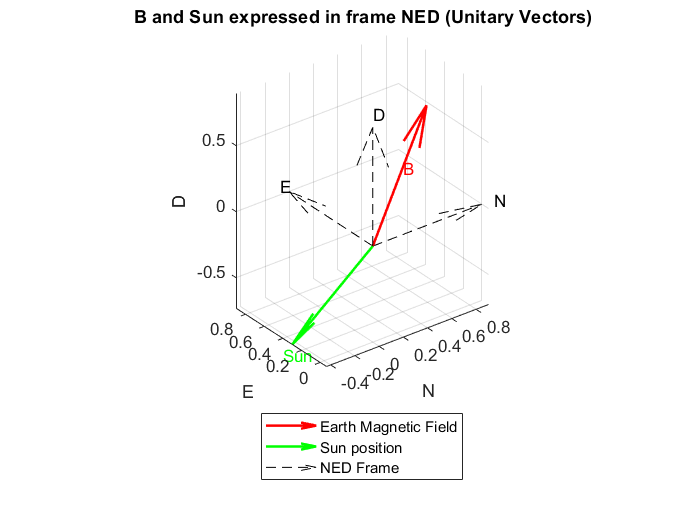

figure()
%%%Convert NED (North East Down to X,Y,Z in ECI frame)
%%%First we need to create a rotation matrix from the NED frame to the 
%%%inertial frame
phiE = 0;
thetaE = acos(positionGCRF(3)/norm(positionGCRF));
psiE = atan2(positionGCRF(2),positionGCRF(1));
rot_NED_I = TIB(phiE,thetaE+pi,psiE);                    %NED to inertial Rotation matrix

%%Plot Magnetic field
[h1,~] = plotVector(zeros(1,3),getUnitVector(xyz),1,'r-','B','m'); hold on
%%Plot NED frame
[h2,~] = plotVector(zeros(1,3),[1,0,0],1,'k--','N','e');
[h3,~] = plotVector(zeros(1,3),[0,1,0],1,'k--','E','e');
[h4,~] = plotVector(zeros(1,3),[0,0,1],1,'k--','D','e');
%%Plot sun vector
[h5,~] = plotVector(zeros(1,3),rot_NED_I'*sun_i',1,'g-','Sun','e');
%%Grafic settings
xlabel('N'); ylabel('E'); zlabel('D');
title('B and Sun expressed in frame NED (Unitary Vectors)');
set(h1,'LineWidth',1.5,'MaxHeadSize',1); set(h2,'MaxHeadSize',1);
set(h3,'MaxHeadSize',1); set(h4,'MaxHeadSize',1);
set(h5,'LineWidth',1.5,'MaxHeadSize',1); 
legend([h1,h5,h2],'Earth Magnetic Field','Sun position','NED Frame','Location','southoutside');
axis equal;

#### **1.1.2 Inertial Frame**

Get Satellite position in the inertial frame.

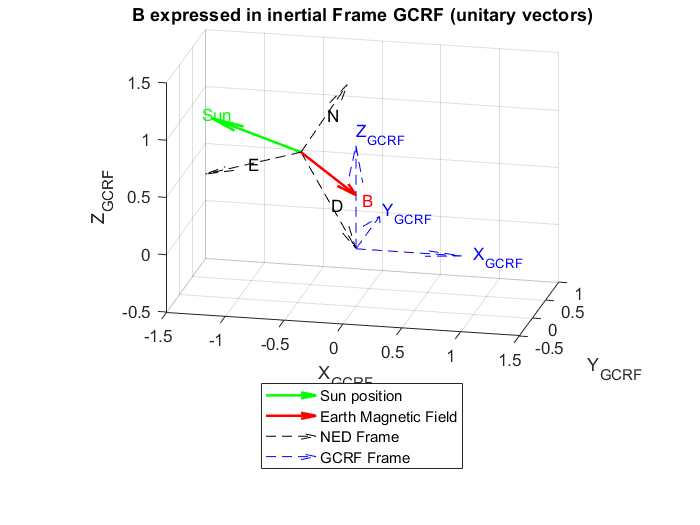

[positionGCRF, velGCRF] = states(satSGP4,stopTime,"CoordinateFrame", "inertial");

r_ecef = eci2ecef(datevec(stopTime),positionGCRF);
positionSGP41 = ecef2lla(r_ecef', 'WGS84');

%%%Convert NED (North East Down to X,Y,Z in ECI frame)
%%%First we need to create a rotation matrix from the NED frame to the 
%%%inertial frame
phiE = 0;
thetaE = acos(positionGCRF(3)/norm(positionGCRF));
psiE = atan2(positionGCRF(2),positionGCRF(1));
rot_NED_I = TIB(phiE,thetaE+pi,psiE);   %NED to inertial Rotation matrix

figure()
%%Plot sun vector
[h0,~] = plotVector(getUnitVector(positionGCRF),sun_i,1,'g-','Sun','e'); hold on
set(h0,'LineWidth',1.5,'MaxHeadSize',1);
%%Plot B vector
[h1,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I*getUnitVector(xyz),1,'r-','B','e'); hold on
set(h1,'LineWidth',1.5,'MaxHeadSize',1);
%%Plot NED frame
[h2,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,1),1,'k--','N','m');
[h3,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,2),1,'k--','E','m');
[h4,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,3),1,'k--','D','m');
set(h2,'MaxHeadSize',1);set(h3,'MaxHeadSize',1);set(h4,'MaxHeadSize',1);
%%Plot GCRF frame
[h5,~] = plotVector(zeros(1,3),[1,0,0],1,'b--','X_{GCRF}','e');
[h6,~] = plotVector(zeros(1,3),[0,1,0],1,'b--','Y_{GCRF}','e');
[h7,~] = plotVector(zeros(1,3),[0,0,1],1,'b--','Z_{GCRF}','e');
set(h5,'MaxHeadSize',1);set(h6,'MaxHeadSize',1);set(h7,'MaxHeadSize',1);
%%%Graphics settings
legend([h0,h1,h2,h5],'Sun position','Earth Magnetic Field','NED Frame', 'GCRF Frame','Location','southoutside');
xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}');
title('B expressed in inertial Frame GCRF (unitary vectors)'); axis equal;
xlim([-1.5 1.5]);ylim([-0.5 1.0]);zlim([-0.5 1.5]);
view([12.54 17.82]);

#### **1.1.3  Orbit Frame**

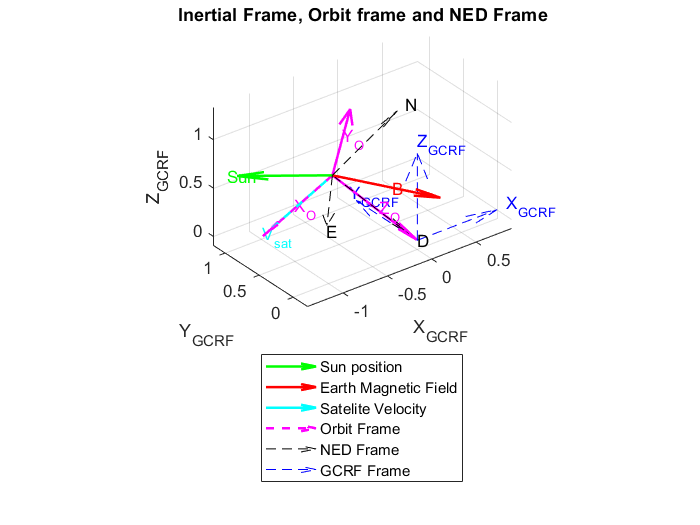

%%Alignt X_o vector in direction of satellite velocity and Zvector to
%%nadir pointing vector
oX=getUnitVector(velGCRF); oZ=-1*getUnitVector(positionGCRF); oY=cross(oZ,oX);
rot_orbit_I=horzcat(oX,oY,oZ);

figure()
%%Plot sun vector
[h0,~] = plotVector(getUnitVector(positionGCRF),sun_i,1,'g-','Sun','e'); hold on
set(h0,'LineWidth',1.5,'MaxHeadSize',1);

%%% Plot satelite velocity and B campus
[h1,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I*getUnitVector(xyz),1,'r-','B','m'); hold on
[h2,~] = plotVector(getUnitVector(positionGCRF),getUnitVector(velGCRF),1,'c.','V_{sat}','e'); hold on
set(h1,'LineWidth',1.5,'MaxHeadSize',1); set(h2,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot orbit frame
[h3,~] = plotVector(getUnitVector(positionGCRF),rot_orbit_I(:,1),1,'m--','X_{O}','m');
[h4,~] = plotVector(getUnitVector(positionGCRF),rot_orbit_I(:,2),1,'m-' ,'Y_{O}','m');
[h5,~] = plotVector(getUnitVector(positionGCRF),rot_orbit_I(:,3),1,'m-' ,'Z_{O}','m');
set(h3,'LineWidth',1.5,'MaxHeadSize',1); set(h4,'LineWidth',1.5,'MaxHeadSize',1); set(h5,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot NED frame
[h6,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,1),1,'k--','N','e');
[h7,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,2),1,'k--','E','e');
[h8,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,3),1,'k--','D','e');
set(h6,'MaxHeadSize',1); set(h7,'MaxHeadSize',1); set(h8,'MaxHeadSize',1);

%%Plot GCRF frame
[h9 ,~]  = plotVector(zeros(1,3),[1,0,0],1,'b--','X_{GCRF}','e');
[h10,~]  = plotVector(zeros(1,3),[0,1,0],1,'b--','Y_{GCRF}','e');
[h11,~]  = plotVector(zeros(1,3),[0,0,1],1,'b--','Z_{GCRF}','e');
set(h9,'MaxHeadSize',1); set(h10,'MaxHeadSize',1); set(h11,'MaxHeadSize',1);

legend([h0,h1,h2,h3,h6,h9],'Sun position','Earth Magnetic Field','Satelite Velocity','Orbit Frame','NED Frame', 'GCRF Frame','Location','southoutside');
set(h8,'MaxHeadSize',1); set(h9,'MaxHeadSize',1); set(h10,'MaxHeadSize',1);
xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}');
title('Inertial Frame, Orbit frame and NED Frame');
axis equal;

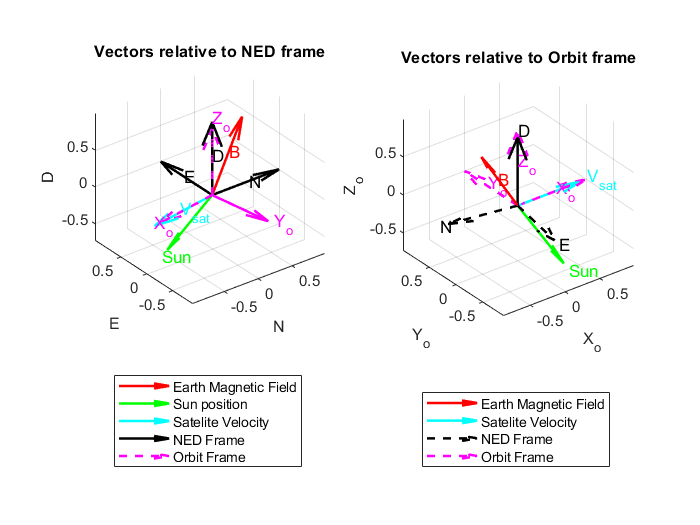

figure()
subplot(1,2,1)
% %%% Get rotation quaternion from NED to orbit frame 
D_v = [0,0,1]';
A = norm(cross(rot_NED_I(:,1),getUnitVector(velGCRF)));
B = dot(rot_NED_I(:,1),getUnitVector(velGCRF));
angle = atan2(A,B);
q_NED_o = [cos(angle/2), D_v(1)*sin(angle/2), D_v(2)*sin(angle/2), D_v(3)*sin(angle/2)]; 

%%Plot NED Frame
 [h1,~] = plotVector(zeros(1,3),[1,0,0]',1,'k-','N','m'); hold on;
 [h2,~] = plotVector(zeros(1,3),[0,1,0]',1,'k-','E','m');
 [h3,~] = plotVector(zeros(1,3),[0,0,1]',1,'k-','D','m');
 set(h1,'LineWidth',1.5,'MaxHeadSize',1); set(h2,'LineWidth',1.5,'MaxHeadSize',1); set(h3,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot Sat vel in NED frame
 [h4,~] = plotVector(zeros(1,3),rot_NED_I'*getUnitVector(velGCRF),1,'c-','V_{sat}','m');
 set(h4,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot Orbit frame
 [h5,~] = plotVector(zeros(1,3),quatRotation(quatconj(q_NED_o),[1,0,0]'),1,'m--','X_o','e');
 [h6,~] = plotVector(zeros(1,3),quatRotation(quatconj(q_NED_o),[0,1,0]'),1,'m-','Y_o','e');
 [h7,~] = plotVector(zeros(1,3),quatRotation(quatconj(q_NED_o),[0,0,1]'),1,'m--','Z_o','e');
 set(h5,'LineWidth',1.5,'MaxHeadSize',1); set(h6,'LineWidth',1.5,'MaxHeadSize',1); 
 set(h7,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot B vector
 [h8,~] = plotVector(zeros(1,3),getUnitVector(xyz),1,'r-','B','m');
 set(h8,'LineWidth',1.5,'MaxHeadSize',1);
 
%%Plot Sun vector
 [h9,~] = plotVector(zeros(1,3),rot_NED_I'*sun_i',1,'g-','Sun','e');
 set(h9,'LineWidth',1.5,'MaxHeadSize',1);
 
%%Graphics secttings
legend([h8,h9,h4,h1,h5],'Earth Magnetic Field','Sun position','Satelite Velocity','NED Frame','Orbit Frame','Location','southoutside');
xlabel('N'); ylabel('E'); zlabel('D');
title('Vectors relative to NED frame'); axis equal;

subplot(1,2,2)
%%Plot Orbit Frame
 [h1,~] = plotVector(zeros(1,3),[1,0,0]',1,'m--','X_o','m'); hold on;
 [h2,~] = plotVector(zeros(1,3),[0,1,0]',1,'m--','Y_o','m');
 [h3,~] = plotVector(zeros(1,3),[0,0,1]',1,'m--','Z_o','m');
 set(h1,'LineWidth',1.5,'MaxHeadSize',1); set(h2,'LineWidth',1.5,'MaxHeadSize',1); set(h3,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot Sat vel in Orbit frame
 [h4,~] = plotVector(zeros(1,3),rot_orbit_I'*getUnitVector(velGCRF), 1,'c-','V_{sat}','e');
 set(h4,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot B vector
 [h5,~] = plotVector(zeros(1,3),quatRotation(q_NED_o,getUnitVector(xyz)),1,'r-','B','m');
 set(h5,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot NED frame
 [h6,~] = plotVector(zeros(1,3),quatRotation(q_NED_o,[1,0,0]'),1,'k--','N','e');
 [h7,~] = plotVector(zeros(1,3),quatRotation(q_NED_o,[0,1,0]'),1,'k--','E','e');
 [h8,~] = plotVector(zeros(1,3),quatRotation(q_NED_o,[0,0,1]'),1,'k-', 'D','e');
 set(h6,'LineWidth',1.5,'MaxHeadSize',1); set(h7,'LineWidth',1.5,'MaxHeadSize',1); 
 set(h8,'LineWidth',1.5,'MaxHeadSize',1);
 
 %%Plot Sun vector
 [h9,~] = plotVector(zeros(1,3),rot_orbit_I'*sun_i',1,'g-','Sun','e');
 set(h9,'LineWidth',1.5,'MaxHeadSize',1);

 %%Graphics secttings
 legend([h5,h4,h6,h1],'Earth Magnetic Field','Satelite Velocity','NED Frame','Orbit Frame','Location','southoutside');
 xlabel('X_o'); ylabel('Y_o'); zlabel('Z_o');
 title('Vectors relative to Orbit frame'); axis equal;

**1.1.3. Star sensor simulation**

 %%% Charge star catalog
star_catalog = read_catalog(6.5);

Limiting Magnitude = 6.50
Number of stars = 8789


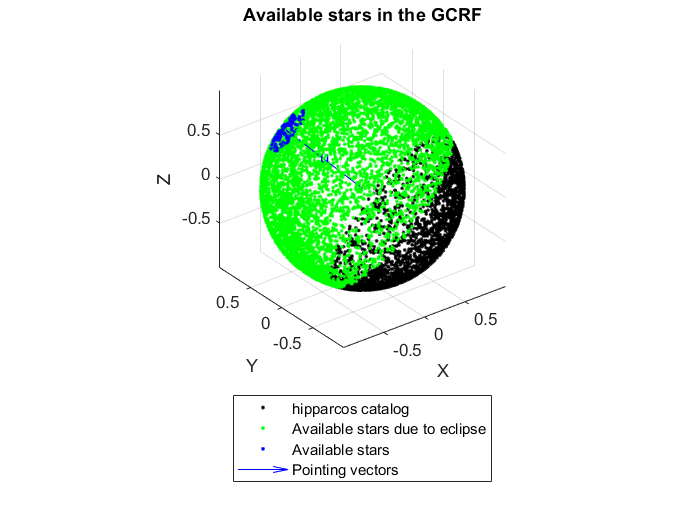


 %%%Algorithm to obtain the available stars
 %%%Determine available stars due to eclipse and update catalog
 a = eclipse(positionGCRF*1e-3,1e15*star_catalog(:,4:6)); index = find(a==1); 
 aval_star = star_catalog(index,:); 
 %%%Determine the pointing vector (-z axis on body frame)
 b_u_point = quatRotation([1,0,0,0], [0,0,-1]); u_point = rot_orbit_I*b_u_point';    
 %%%Determine star sensor readings
 [seg, real_id] = select_region_fov(aval_star, 30, u_point, rot_orbit_I');
 
 %%%Plot results
 figure()
 h1 = plot3(star_catalog(:,4),star_catalog(:,5),star_catalog(:,6),'k.'); hold on; axis equal; grid on
 h2 = plot3(aval_star(:,4),aval_star(:,5),aval_star(:,6),'g.');
 h3 = plot3(seg(:,4),seg(:,5),seg(:,6),'b.'); 
 [h4,~] = plotVector([0,0,0],u_point/norm(u_point),1,'b-','u','m'); xlabel('X'); ylabel('Y'); zlabel('Z');
 title('Available stars in the GCRF');
 legend([h1,h2,h3,h4],'hipparcos catalog','Available stars due to eclipse','Available stars','Pointing vectors','Location','southoutside');

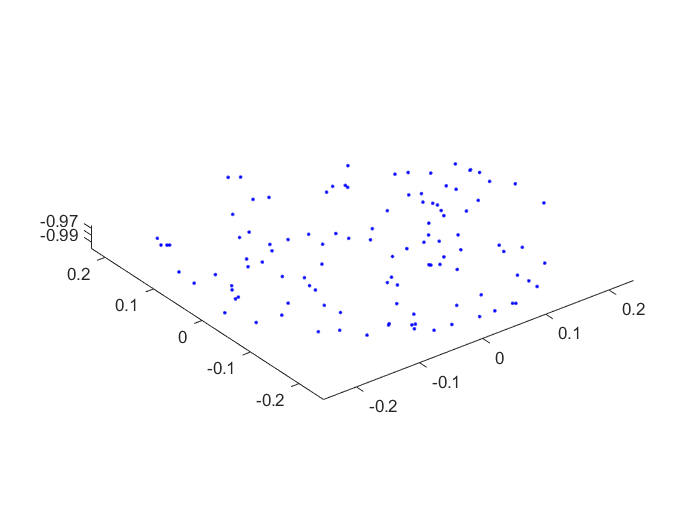

 figure()
 h3 = plot3(seg(:,7),seg(:,8),seg(:,9),'b.'); axis equal;

#### 1.3.5. Start Satellite Simulation (With SPG4 propagator)

**1.3.3. Satellite Parameters**

Clear and errase variables.

clear;
clc;

**1.3.6. Sensor Parameters**

sensors.mag.desvEst = 50.00e-9; %T
sensors.mag.res     = 31.25e-9; %T
sensors.mag.normDesvEst =  0.5;

%sensors.sunSensor.desvEst   = 0.010000; %deg
sensors.sunSensor.normDesvEst   = 0.00300;
sensors.sunSensor.desvEst       = 0.050000; %deg
sensors.sunSensor.res           = 0.500000; %deg
sensors.sunSensor.t_glass       = 0.448000; %cm
sensors.sunSensor.n_refrac      = 1.455300;
sensors.sunSensor.sun_scale     = 0.002754; %cm/count
sensors.sunSensor.sun_bias      =-0.350625; % cm

sensors.starSensor.limiMagnigtude = 6.5;
sensors.starSensor.FOV = 10; %Deg
sensors.starSensor.normDesvEst   = 0.00300;

- **Satellite inertia**

%%%Inertia tens
sat.Is = [0.103682,-0.001094, 0.015519;...
         -0.001094, 0.104158,-02.57e-6;...
          0.015519, 02.57e-6, 0.088588];
sat.mass = 32; %Kg

- **Earth Parameters**

%%%%This will define all of our planet parameters
earth.Radius       = 6378E3;               %% Planet Radius (meters)
earth.Mass         = 5.972E24;             %% Planet Mass (kg)
earth.GravityConst = 6.674E-11;            %% Planet gravity constan (Nm^2/kg^2)
earth.mu           = earth.GravityConst*earth.Mass;        %% G*M product (Nm^2/kg)

- **Orbit Parameters**

%% Orbit Parameters
%%%Orbital parameters
orbit.altitude    = 500E3;   
orbit.semiMajorAxis = orbit.altitude+earth.Radius;
orbit.eccentricity = 0;
orbit.inclination = 97.34; 
orbit.rightAscensionOfAscendingNode = 313.131; 
orbit.argumentOfPeriapsis = 0; 
orbit.trueAnomaly = 0;
orbit.period      = 2*pi/sqrt(earth.mu)*orbit.semiMajorAxis^(3/2); % Orbital period
orbit.vcircular   = sqrt(earth.mu/orbit.semiMajorAxis);            % Circular velocity

- **Satellite Disturbances**

%%% External diisturbances
disturbance = @(state) dist_gravityGrad(state,sat,orbit,earth);

- **Initial conditions**

%% Initial Conditions
%%% Intitial Conditions for Attitude and Angular Velocity (Euler angles)
initial.atitude.rpy0_deg(1)    = 0;           %  Initial Roll  (deg)
initial.atitude.rpy0_deg(2)    = 0;           %  Initial Pitch (deg)
initial.atitude.rpy0_deg(3)    = 0;           %  Initial Yaw   (deg)
%%% Initial Euler Angles and quaternions
initial.atitude.rpy0_rad    = deg2rad([initial.atitude.rpy0_deg(1),...
                                       initial.atitude.rpy0_deg(2),...
                                       initial.atitude.rpy0_deg(3)]');       % Euler Angles (rad)
initial.atitude.q0123_0 = EulerAngles2Quaternions(initial.atitude.rpy0_rad);  % Quaternions
%%% Initial angular rates in the body frame (rad/s)
initial.omega.omega0_x = 0.0;
initial.omega.omega0_y = 0.0;
initial.omega.omega0_z = 0.0;

## Obtain the magnetic Field

settings.B_earth_field.model_epoch = '2020';
settings.B_earth_field.decimal_year = 2020 ;
settings.wgs84 = wgs84Ellipsoid;

#### 1.3.4. Start Satellite Simulation (SPG4 propagator)

- **Simulation Settings**

%% Simulation Parameters
%%% Setting Time Window (just 5 orbit)
settings.startTime = datetime(2023,08,30,12,35,38);
settings.sampleTime = 120;
settings.number_of_orbits = 5;
settings.tfinal = orbit.period*settings.number_of_orbits;
settings.stopTime = settings.startTime  + seconds(orbit.period*settings.number_of_orbits);

%%% Satellite initial states
settings.X0 = [initial.atitude.q0123_0; initial.omega.omega0_x; ...
               initial.omega.omega0_y ; initial.omega.omega0_z];

%% Create satellite scenario to use SPG4 propagator
sc = satelliteScenario(settings.startTime ,settings.stopTime,settings.sampleTime);
sat.satSGP4 = satellite(sc, orbit.semiMajorAxis, orbit.eccentricity, orbit.inclination, ...
        orbit.rightAscensionOfAscendingNode, orbit.argumentOfPeriapsis, orbit.trueAnomaly);

- **Simulation **


%% Solve by variable step Runge Kutta of 4 order and use SPG4 propagator 
tic
opts = odeset('InitialStep',1e-4,'RelTol',1e-6);
settings.hWaitbar = waitbar(0, 'Progress: 0%','Name', 'GWSAT-1 Simulation Progress');
[tout,x] = ode45(@(t,x) satelliteSPG4sim(t, x, sat, disturbance, settings),...
    [0 settings.tfinal],settings.X0,opts);
elapsedTime = toc;

%%%Preallocate variables
dis_v     = zeros(3,length(x));
xyzout    = zeros(3,length(x));
B_ref     = zeros(length(x),3);
B_body    = zeros(length(x),3);
B_body_n  = zeros(length(x),3);
sun_ref   = zeros(length(x),3);
sun_body  = zeros(length(x),3);
sun_body_n= zeros(length(x),3);
q_est_triad1  = zeros(length(x),4);
q_est_triad2  = zeros(length(x),4);
q_est_opTriad = zeros(length(x),4);
q_est_quest   = zeros(length(x),4);

sun_avail = zeros(length(x),1);

%%% Charge star catalog
star_catalog = read_catalog(sensors.starSensor.limiMagnigtude);

Limiting Magnitude = 6.50
Number of stars = 8789



%%%Run algorithms
for i = 1:length(x)
    %%%Recover time
    datetime_t = settings.startTime  + seconds(tout(i));
    %%%Recover disturbances
    dis_v(:,i) = disturbance([zeros(1,6),x(i,:)]);
    %%%Recover position
    [positionGCRF, velGCRF] = states(sat.satSGP4,datetime_t,"CoordinateFrame", "inertial");
    xyzout(:,i) = eci2ecef(datevec(datetime_t),positionGCRF);
    llaSPG4 = ecef2lla(xyzout(:,i)', 'WGS84');
        
    %%%Recover magnetic field
    %%% Use LLA to get value models of magnetic field (XYZ in NED frame) 
    [xyz, ~, ~, ~, ~] = wrldmagm(llaSPG4(3), llaSPG4(1),llaSPG4(2),...
            settings.B_earth_field.decimal_year, settings.B_earth_field.model_epoch);             
    
    %%%Get quaterion from NED frame to orbit frame
    %%%Create a rotation matrix from the NED frame to the GCRF inertial frame
    phiE   = 0;
    thetaE = acos(positionGCRF(3)/norm(positionGCRF));
    psiE   = atan2(positionGCRF(2),positionGCRF(1));
    
    %%%Got the inertial Rotation matrix
    rot_NED_I = TIB(phiE,thetaE+pi,psiE);   
    
    %%% Get rotation matrix from orbit to inertia
    oX=getUnitVector(velGCRF); oZ=-1*getUnitVector(positionGCRF); oY=cross(oZ,oX);
    rot_orbit_I=horzcat(oX,oY,oZ);
    %%% Get rotation quaternion from NED to orbit frame
    D_v = [0,0,1]';
    A = norm(cross(rot_NED_I(:,1),getUnitVector(velGCRF)));
    B = dot(rot_NED_I(:,1),getUnitVector(velGCRF));
    angle = atan2(A,B);
    q_NED_o = [cos(angle/2), D_v(1)*sin(angle/2), D_v(2)*sin(angle/2), D_v(3)*sin(angle/2)]; 
    
    %%% Turn NED frame into Orbit frame
    B_ref(i,:) = quatRotation(q_NED_o,xyz)*1E-9; %In Teslas
    %%% Turn reference to BodyFrame
    B_body(i,:) = quatRotation(quatconj(x(i,1:4)), B_ref(i,:));
    B_body_n(i,:) = mag_model(B_body(i,:),sensors.mag.desvEst,sensors.mag.res);
    
    %%%Recover sun Reference (in IGRF)
    [sun_i,r_sun] = solar(datetime_t.Year,datetime_t.Month,datetime_t.Day,datetime_t.Hour,datetime_t.Minute,datetime_t.Second);
    %%%Determine eclipse condition
    sun_avail(i) = eclipse(positionGCRF*1e-3,r_sun*1e-3*sun_i);
    
    %%%Algorithm to obtain the available stars
    %%%Determine available stars due to eclipse and update catalog
    a = eclipse(positionGCRF*1e-3,1e15*star_catalog(:,4:6)); index = find(a==1); 
    aval_star = star_catalog(index,:); 
    %%%Determine the pointing vector
    b_u_point = quatRotation(x(i,1:4), [0,0,-1]); u_point = rot_orbit_I*b_u_point';    
    %%%Determine star sensor readings
    [seg_ref, real_id] = select_region_fov(aval_star, sensors.starSensor.FOV, u_point, rot_orbit_I');
    [a1,a2] = size(seg_ref); seg_body = zeros(a1,3);
    for ii = 1:a1
        seg_body(ii,:) = quatRotation(quatconj(x(i,1:4)), seg_ref(ii,7:9));
    end
    
    %%%Determine attitude matrix
    %q_est_quest(i,:) = QUEST([B_body_n(i,:);sun_body_n(i,:);seg_body]', [B_ref(i,:); sun_ref(i,:); seg_ref(:,7:9)]', ones(1,a1+2));  
    q_est_quest(i,:) = QUEST(seg_body', seg_ref(:,7:9)', ones(1,a1+2)); 
        
    if sun_avail(i) == 1
        sun_ref(i,:) = rot_orbit_I'*sun_i';
        %%% Turn reference to BodyFrame
        sun_body(i,:)   = quatRotation(quatconj(x(i,1:4)), sun_ref(i,:));
        sun_body_n(i,:) = sun_sensor_sampex_model(sun_body(i,:),sensors.sunSensor.n_refrac,sensors.sunSensor.t_glass,...
                                     sensors.sunSensor.res,sensors.sunSensor.desvEst);
        %%%Determine attitude matrix
        A_triad1 = triad_algorithm(B_ref(i,:), sun_ref(i,:),B_body_n(i,:),sun_body_n(i,:));
        %%%Determine attitude matrix
        A_triad2 = triad_algorithm(sun_ref(i,:),B_ref(i,:),sun_body_n(i,:),B_body_n(i,:));
        %%%Determine attitude matrix
        A_optTriad = optTriad_algorithm(A_triad1,A_triad2,sensors.mag.normDesvEst,sensors.sunSensor.normDesvEst);
                 
        
        %%%Determine 
        %%%Get quaternions
        if isnan(A_triad1)
            q_est_triad1(i,:) = nan(1,4);
        else
            q_est_triad1(i,:) = rotm2quat(A_triad1);
        end
        %%%Get quaternions
        if isnan(A_triad2)
            q_est_triad2(i,:) = nan(1,4);
        else
            q_est_triad2(i,:) = rotm2quat(A_triad2);
        end        
        %%%Get quaternions
        if isnan(A_optTriad)
            q_est_opTriad(i,:) = nan(1,4);
        else
            q_est_opTriad(i,:) = rotm2quat(A_optTriad);
        end    
        
    end
   
end

% Print the elapsed time in seconds
fprintf('Elapsed time: %.3f miliseconds\n',elapsedTime*1000);

Elapsed time: 7136.657 miliseconds


**Run attitude determination simulation**

sune=kron(ones(300,1),sun_body(113,:));
sun_bm = [];
for i = 1:length(sune)
    a = sun_sensor_sampex_model(sune(i,:),sensors.sunSensor.n_refrac,sensors.sunSensor.t_glass,...
    sensors.sunSensor.res,sensors.sunSensor.desvEst);
    b = getUnitVector(a);
    sun_bm = [sun_bm,b];
end
desv = max(std(sun_bm'))

desv = NaN

mag_b=kron(ones(300,1),B_body(20,:));
mag_bm = [];
for i = 1:length(mag_b)
    a = mag_model(mag_b(i,:),sensors.mag.desvEst,sensors.mag.res);
    b = getUnitVector(a);
    mag_bm = [mag_bm,b];
end
desv = max(std(mag_bm'))

desv = 0.5036

% %%Preallocate variables
% dis_v = zeros(length(x),3);
% sun_i = zeros(length(x),3);
% sun_o = zeros(length(x),3);
% sun_b = zeros(length(x),3);
% 
% for i=1:length(x)
%     datetime_t = settings.startTime  + seconds(tout(i));
%     %%Recover sun position measurement
%     [positionGCRF, velGCRF] = states(sat.satSGP4,datetime_t,"CoordinateFrame", "inertial");
%     
%     
%     dis_v(:,i)  = disturbance([zeros(1,6),x(i,:)]);
%     
%     %%% Get state in geodetic and inertial reference frames.
%     xyzout(:,i) = eci2ecef(datevec(datetime_t),positionGCRF);
%     llaSPG4 = ecef2lla(xyzout(:,i)', 'WGS84');
% 
%     %%%Create a rotation matrix from the NED frame to the GCRF inertial frame
%     phiE = 0;
%     thetaE = acos(positionGCRF(3)/norm(positionGCRF));
%     psiE = atan2(positionGCRF(2),positionGCRF(1));
%     %%%Got the inertial Rotation matrix
%     rot_NED_I = TIB(phiE,thetaE+pi,psiE);   
%     %%% Get rotation quaternion from NED to orbit frame
%     D_v = [0,0,1]';
%     A = norm(cross(rot_NED_I(:,1),getUnitVector(velGCRF)));
%     B = dot(rot_NED_I(:,1),getUnitVector(velGCRF));
%     angle = atan2(A,B);
%     q_NED_o = [cos(angle/2), D_v(1)*sin(angle/2), D_v(2)*sin(angle/2), D_v(3)*sin(angle/2)]; 
% 
%     %%% Use LLA to get value models of magnetic field (XYZ in NED frame) 
%     [xyz, ~, ~, ~, ~] = wrldmagm(llaSPG4(3), llaSPG4(1),llaSPG4(2),...
%             settings.B_earth_field.decimal_year, settings.B_earth_field.model_epoch);             
%     
%     %%% Turn NED frame into Orbit frame
%     B_ref = quatRotation(q_NED_o,xyz)*1E-9; %In Teslas
%     %%% Turn reference to BodyFrame
%     B_body = quatRotation(quatconj(x(i,1:4)), B_ref);
%     %%% Store magnetic field
%     magnCampus(:,i) = B_body';
%     
%     %%% Add mag field
%     Torque_mag_v(:,i) = detumblingControl(x(i,:),6e3,B_body);
%     
%     
%     
%     
%     %%Get rotation matrix from orbit frame to ineria frame
%     oX=getUnitVector(velGCRF); oZ=-1*getUnitVector(positionGCRF); oY=cross(oZ,oX);
%     rot_orbit_I=horzcat(oX,oY,oZ);
%     
%     %%%Sun Reference relative to inertia frame
%     sun_i(i,:) = solar(datetime_t.Year,datetime_t.Month,datetime_t.Day,datetime_t.Hour,datetime_t.Minute,datetime_t.Second);
%     %%%Sun reference relative to orbit frames
%     sun_o(i,:) = [rot_orbit_I'*sun_i(i,:)']';
%     %%%Sun reference relative to body frame
%     sun_b(i,:) = quatRotation(quatconj(x(i,1:4)), sun_o(i,:));
% end

Plot new figures with the new project

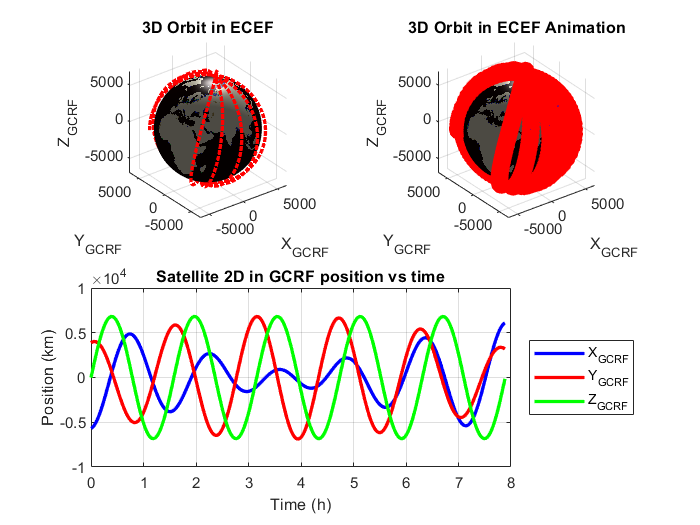

%% Rename index
q0123out = x(:,1:4);                           %%Satellite quaternions
ptpout = Quaternions2EulerAngles(q0123out);    %%Satellite euler angles
pqrout = x(:,5:7);                             %%Angular Rates

%% Plot 2D position
%%%Plot satellite position as a function of time
figure();
    subplot(2,1,2);
    h1 = plot(tout/3600,xyzout(1,:)/1E3,'b-','LineWidth',2); hold on; grid on;
    h2 = plot(tout/3600,xyzout(2,:)/1E3,'r-','LineWidth',2);
    h3 = plot(tout/3600,xyzout(3,:)/1E3,'g-','LineWidth',2);
    xlabel('Time (h)'); ylabel('Position (km)');
    legend('X_{GCRF}','Y_{GCRF}','Z_{GCRF}','Location','eastoutside');
    title('Satellite 2D in GCRF position vs time');

%% Plot 3D position
subplot(2,2,1)
    %%%Build Earth
    %%%Load earth elevation data
    load('topo.mat', 'topo', 'topomap1');
    %%%Obtain elevation data size
    [rows, cols] = size(topo);
    %%%Create 3D earth sphere
    [X, Y, Z] = sphere(rows-1, cols-1);
    X = X*earth.Radius/1000;
    Y = Y*earth.Radius/1000;
    Z = Z*earth.Radius/1000;
    %%%Draw earth in Km and satellite orbit
    h0 = plot3(xyzout(1,:)/1000,xyzout(2,:)/1000,xyzout(3,:)/1000,'r:','LineWidth',2);
    xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}')
    grid on
    hold on
    surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct');
    %legend(h0,'Satellite orbit (Km)','Location','southoutside');
    colormap(topomap1);
    axis equal
    %%%Set view and ilumination
    light('Position', [1 1 1]);
    lighting gouraud;
    view(3);
    %%%Add title
    title('3D Orbit in ECEF')
    
% Draw earth in Km and satellite orbit
subplot(2,2,2);
    h1 = plot3(xyzout(1,:)/1000,xyzout(2,:)/1000,xyzout(3,:)/1000,'ro','LineWidth',5);
    hold on;
    h2 = plot3(xyzout(1,:)/1000,xyzout(2,:)/1000,xyzout(3,:)/1000,'b:','LineWidth',1);
    xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}');
    grid on; hold on;
    surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct');
    colormap(topomap1);
    axis equal
    % Set view and ilumination
    light('Position', [1 1 1]);
    lighting gouraud;
    view(3);
    % Add title
    title('3D Orbit in ECEF Animation')

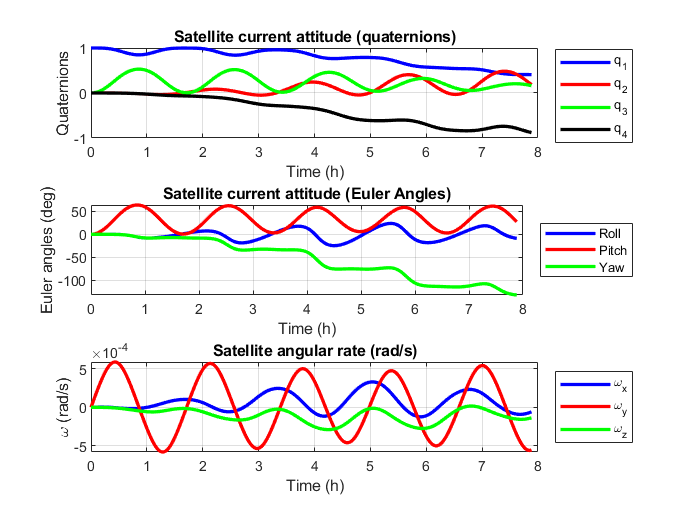

figure();
subplot(3,1,1)
h1 = plot(tout/3600,q0123out(:,1),'b-','LineWidth',2);
hold on
grid on
h2 = plot(tout/3600,q0123out(:,2),'r-','LineWidth',2);
h3 = plot(tout/3600,q0123out(:,3),'g-','LineWidth',2);
h4 = plot(tout/3600,q0123out(:,4),'k-','LineWidth',2);
xlabel('Time (h)');
ylabel('Quaternions');
legend([h1,h2,h3,h4],'q_1','q_2','q_3','q_4','Location','eastoutside');
title('Satellite current attitude (quaternions)');

subplot(3,1,2)
h1 = plot(tout/3600,rad2deg(ptpout(:,1)),'b-','LineWidth',2);
hold on; grid on;
h2 = plot(tout/3600,rad2deg(ptpout(:,2)),'r-','LineWidth',2);
h3 = plot(tout/3600,rad2deg(ptpout(:,3)),'g-','LineWidth',2);
xlabel('Time (h)');
ylabel('Euler angles (deg)');
legend([h1,h2,h3],'Roll','Pitch','Yaw','Location','eastoutside');
title('Satellite current attitude (Euler Angles)');
subplot(3,1,3)
h1 = plot(tout/3600,pqrout(:,1),'b-','LineWidth',2);
hold on
grid on
h2 = plot(tout/3600,pqrout(:,2),'r-','LineWidth',2);
h3 = plot(tout/3600,pqrout(:,3),'g-','LineWidth',2);
xlabel('Time (h)');
ylabel('\omega (rad/s)');
legend([h1,h2,h3],'\omega_x','\omega_y','\omega_z','Location','eastoutside');
title('Satellite angular rate (rad/s)');

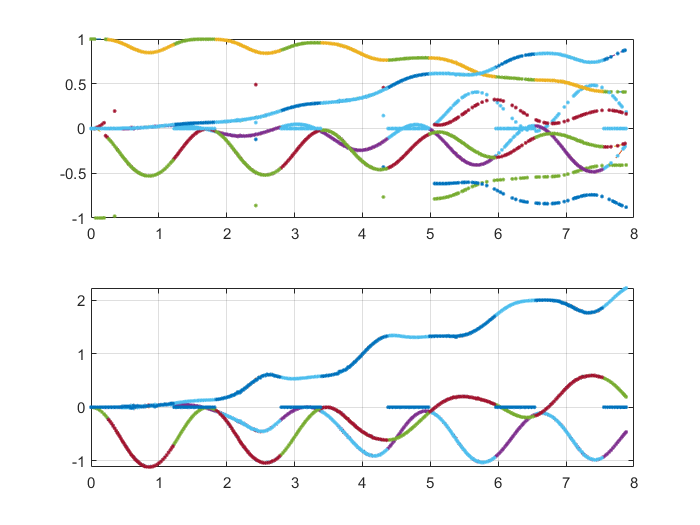

%%Compare attitude determination algorithms
figure()
subplot(2,1,1)
plot(tout/3600,quatconj(x(:,1:4)),'--');hold on; grid on;
plot(tout/3600,q_est_quest,'.'); 
plot(tout/3600,q_est_triad1,'.');
plot(tout/3600,q_est_triad2,'.');
plot(tout/3600,q_est_opTriad,'.');
subplot(2,1,2)
plot(tout/3600,Quaternions2EulerAngles(quatconj(x(:,1:4))),'--');hold on; grid on;
plot(tout/3600,Quaternions2EulerAngles(q_est_quest),'.'); 
plot(tout/3600,Quaternions2EulerAngles(q_est_triad1),'.');
plot(tout/3600,Quaternions2EulerAngles(q_est_triad2),'.');
plot(tout/3600,Quaternions2EulerAngles(q_est_opTriad),'.');

function [x_dot] = mySatellite(t, x, sat, earth , Td)
%%% Inputs
% t: current time
% x: satellite state
% sat: Satellite parameters
% earth: Earth parameters
% Td: External Disturbances

%%% Read state input
r   =  x(1:3);
vel =  x(4:6);
q   =  x(7:10);
w   =  x(11:13);

%% Read Satellite physical parameters
m  = sat.mass;
Is = sat.Is;

%%%Translational Dynamics
%%%Earth gravity Model
rho = norm(r);
rhat = r/rho;
Fgrav = -(earth.GravityConst*earth.Mass*m/rho^2)*rhat;
F = Fgrav;
accel = F/m;

%%%Rotational Dynamics
%%Book: Fundamentals of Spacecraft Attitude Determination and Control
%%Author: F. Landis Markley & John L. Crassidis
%%Quaternions Kinematics..Ecuación (2.88)
Xi=[-q(2),-q(3),-q(4);
    q(1),-q(4),q(3);
    q(4),q(1),-q(2);
    -q(3),q(2),q(1)];
q_dot=1/2*Xi*w;
%%%Kynematics Equation(3.21)
H = Is*w;                         %Satellite Angular momentun
w_dot = Is\(Td - cross(w,H));     %Dynamics Equatión (3.147)
%%%x_dot Vector
x_dot=[vel;accel;q_dot;w_dot];
end

function [x_dot] = satelliteSim(t, x, sat, earth, dist,settings)
%% Disturbances
%LS2125204: Brayan Espinoza
%%% Get distubance
Td = dist(x);

%%% Satellite model
x_dot = mySatellite(t, x, sat, earth , Td);

%%% Progress bar configuration
%%%% Calculate the progress percentage
progress = t / settings.tfinal;

if isa(settings.hWaitbar,'handle') && isvalid(settings.hWaitbar)
    if t == settings.tfinal
        % Close the progress bar when the simulation is complete
        close(settings.hWaitbar);
    else
        % Update the progress bar
        waitbar(progress, settings.hWaitbar, sprintf('Progress: %.1f%%', progress*100));
    end
end
end

function Tgg = dist_gravityGrad(state,sat,orbit,earth)
% This function calculates the torque produced by the earth's gravity
% gradient.

%% Read inputs
q0123=state(7:10);

%% Gravity disturbances
%R = param{1,2};
%altitude = param{1,3};
%I = param{1,4};

%% Perform calculations (review)
rc = earth.Radius + orbit.altitude;
wo2=3.9833e+14/rc^3;
c3=[2*(q0123(2)*q0123(4)-q0123(3)*q0123(1));
    2*(q0123(3)*q0123(4)+q0123(2)*q0123(1));
    1-2*(q0123(2)^2+q0123(3)^2)];
Tgg=cross(3*wo2*c3,sat.Is*c3);
end

function rotX = quatRotation(q,x)
    qx = [0,x(1),x(2),x(3)];
    q =  reshape(q, 1, []);
    qrotX = quatmultiply(quatmultiply(q, qx), quatconj(q));
    %qrotX = QuaternionsMultiplication(QuaternionsMultiplication(q,qx),QuaternionsConjugate(q));
    rotX = qrotX(2:4);
end

function [x_dot] = mySatelliteSPG4(t, x, sat, Td)
%%% Inputs
% t: current time
% x: satellite state
% sat: Satellite parameters
% earth: Earth parameters
% Td: External Disturbances

%%% Read state input
q   =  x(1:4);
w   =  x(5:7);

%% Read Satellite physical parameters
m  = sat.mass;
Is = sat.Is;

%%%Rotational Dynamics
%%Book: Fundamentals of Spacecraft Attitude Determination and Control
%%Author: F. Landis Markley & John L. Crassidis
%%Quaternions Kinematics..Ecuación (2.88)
Xi=[-q(2),-q(3),-q(4);
    q(1),-q(4),q(3);
    q(4),q(1),-q(2);
    -q(3),q(2),q(1)];
q_dot=1/2*Xi*w;
%%%Kynematics Equation(3.21)
H = Is*w;                         %Satellite Angular momentun
w_dot = Is\(Td - cross(w,H));     %Dynamics Equatión (3.147)
%%%x_dot Vector
x_dot=[q_dot;w_dot];
end

function [x_dot] = satelliteSPG4sim(t, x, sat, dist, settings)
%% Disturbances
%LS2125204: Brayan Espinoza
%%% Get distubance
Td = dist([zeros(6,1);x]);
%datetime_t = settings.startTime  + seconds(t);
%llaSPG4 = states(sat.satSGP4,datetime_t,"CoordinateFrame", "geographic");
%%% Get something whit LLA to evaluate models 

%%% Satellite model
x_dot = mySatelliteSPG4(t, x, sat, Td);

%%% Progress bar configuration
%%%% Calculate the progress percentage
progress = t / settings.tfinal;

if isa(settings.hWaitbar,'handle') && isvalid(settings.hWaitbar)
    if t == settings.tfinal
        % Close the progress bar when the simulation is complete
        close(settings.hWaitbar);
    else
        % Update the progress bar
        waitbar(progress, settings.hWaitbar, sprintf('Progress: %.1f%%', progress*100));
    end
end
end

function A_triad = triad_algorithm(r1,r2,b1,b2)
    %%%Turn vectors in columns
    r1 = reshape(r1, [], 1); r2 = reshape(r2, [], 1); 
    b1 = reshape(b1, [], 1); b2 = reshape(b2, [], 1);
    
    %%%Start triad algorithm
    r1 = getUnitVector(r1); r2 = getUnitVector(r2);
    b1 = getUnitVector(b1); b2 = getUnitVector(b2);
    
    v1 = r1; v2 = cross(r1,r2)/norm(cross(r1,r2)); v3 = cross(v1,v2);
    w1 = b1; w2 = cross(b1,b2)/norm(cross(b1,b2)); w3 = cross(w1,w2);
    %%%Estimate attitude matrix
    %A_triad =[w1,w2,w3]*[v1,v2,v3]';
    A_triad = b1*r1'+(cross(b1,w2))*(cross(r1,v2))'+w2*v2';
end

function A_triad = optTriad_algorithm(A_triad1,A_triad2,std1,std2)
    a=std2^2/(std1^2+std2^2);
    b=std1^2/(std1^2+std2^2);
    
    %%%Start optimized triad algorithm
    AtriadPrime = a*A_triad1+b*A_triad2;
    
    %%%Ortogonalize the matrix
    A_triad = 0.5*(AtriadPrime+inv(AtriadPrime)');
end

function mag_bm = mag_model(mag_b,sig_tam,sig_res)
    %%-----------magnetometerc Model------------
    %%%Add random noise
    mag_b_noise=mag_b+sig_tam*randn(1,3);
    %%%Add resolution
    mag_bm=[round(mag_b_noise(1)/sig_res)*sig_res,...
            round(mag_b_noise(2)/sig_res)*sig_res,...
            round(mag_b_noise(3)/sig_res)*sig_res];   
end
function u = getUnitVector(vector)
    u = vector/norm(vector);
end

**REFERENCES**

[1] Flatley, Thomas W., et al. "On-board attitude determination and control algorithms for SAMPEX." *Proceedings of the 1990 Flight Mechanics/Estimation Theory Symposium*. 1990.

[2] Crasidis

[3]Vallado, David A. *Fundamentals of astrodynamics and applications*. Vol. 12. Springer Science & Business Media, 2001.

[4]Sarpotdar, M., Mathew, J., Sreejith, A. G., K, N., Ambily, S., Prakash, A., ... & Murthy, J. (2017). A software package for evaluating the performance of a star sensor operation. *Experimental Astronomy*, *43*, 99-117.

Chicago